# Linear Control Design 2 - Fall 2020 - Exam Part I

## Introduction

The Part I of the Exam in Linear Control Design 2 (E20) consists of numerical exercises testing the acquisition of competences in the areas of analysis and design of control systems using modern control theory based on state space representation of system dynamics.

**The scoring of each problem is clearly stated.** 

It is the sole responsability of the student to guarantee that the solution delivered for evaluation can be run by the examiner without the need of contacting the student. All dependencies on files external to this Matlab Live Script must be checked and included in the final delivery. **If the examiner will not be able to execute the Matlab Live Script delivered as solution by the student, the Part I will be considered failed.** 

% Fill in your information
Exam = 'LCD2 E20'

Exam = 'LCD2 E20'

Student_Name = 'Student Name'

Student_Name = 'Student Name'

Student_Number = 'Student Number'

Student_Number = 'Student Number'

## Optimal control of a high temperature oven

A high temperature oven with a product to be heat treated is shown in the figure below.

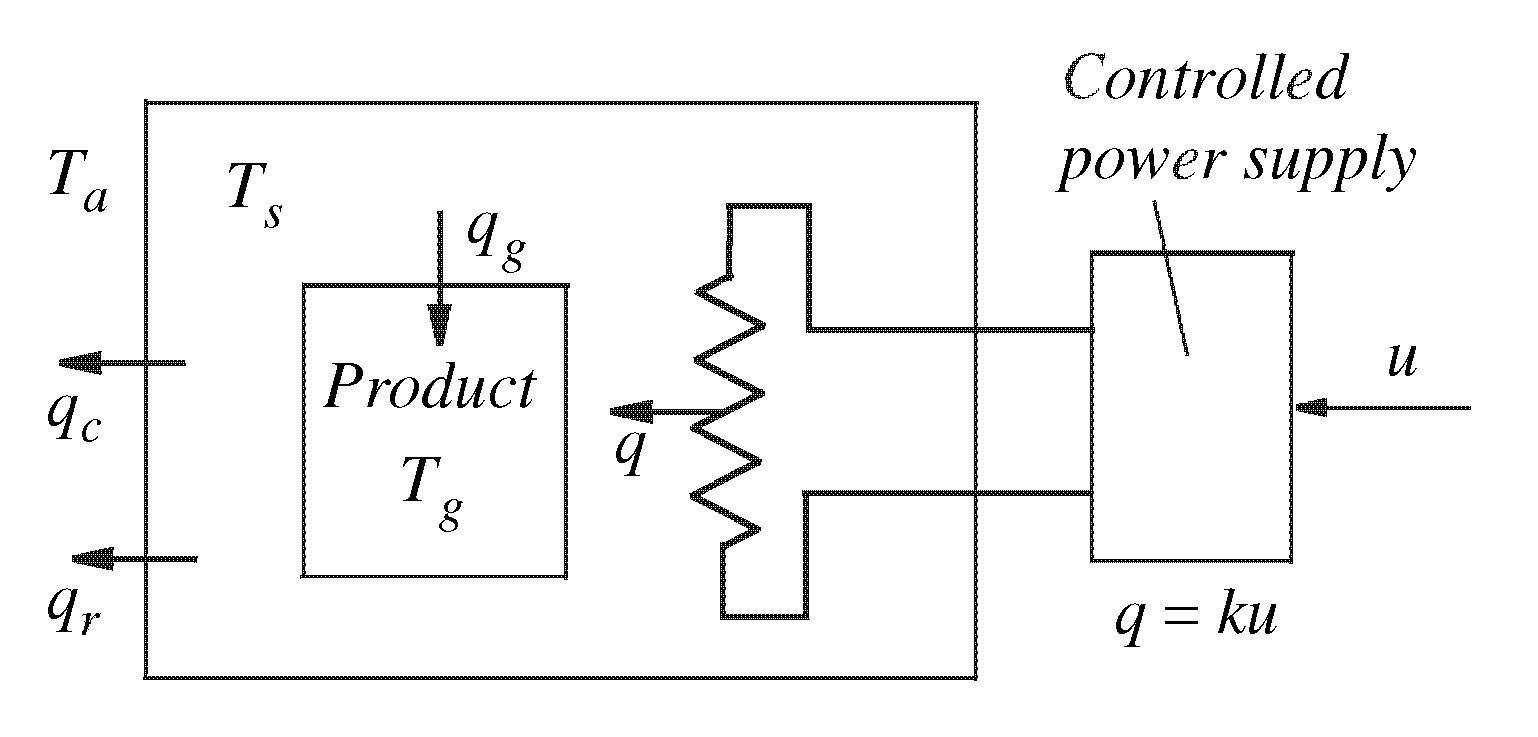

The outer surface temperature $T_s$ of the oven is the same as the temperature in the inner oven space. The ambient temperature is $T_a$ and the product temperature is $T_g$. All the temperatures are assumed to be uniform. The variables denoted $q, \; q_c, \; q_r, \; q_g$ are the heat powers exchanged between the different parts of the system.

The oven surface temperature is so high that the heat loss to the surroundings is not only due to convection but also to radiation. Assume that the convection power is proportional to the temperature difference, i. е.,


$$q_c = k_c(T_s-T_a) \\
q_g = k_g(T_s-T_g)$$


whereas the radiation heat loss follows the Stefan-Boltzmann law,


$$q_r = k_r(T_s^4 - T_a^4)$$


**Note that the temperatures here are absolute temperatures, i.e. measured in Kelvin**. The output is the temperature $T_g$. The total heat capacities of the oven air space and the product are $C_s$ and $C_g$.

The heating element of the oven is connected to a power supply, which is regulated through the voltage input $u$ ranging between 0 and 10 volts. The heat power injected into the oven is given by


$$q = ku$$


### Nonlinear model of the high temperature oven

The nonlinear model describing the dynamical variations of the high temperature oven is dervied by writing out the heat balance equations for the oven surface and the product, i.e.

$C_s\frac{\mathrm{d}T_s}{\mathrm{d}t} = q-q_c-q_g-q_r \\
\qquad \,\,\, = ku - k_c(T_s-T_a) - k_g(T_s - T_g) - k_r (T_s^4-T_a^4) \\
C_g\frac{\mathrm{d}T_g}{\mathrm{d}t}=q_g \\
\qquad \,\,\, = k_g(T_s - T_g) \\
y = T_g
$            (1)

where

- $C_s$ is the heat capacity of the oven

- $C_g$ is the heat capacity of the product

- $k_c$ is the convection constant of the oven

- $k_r$ is the radiation constant of the oven

- $k_g$ is the convection constant of the product

- $k$ is the power constant of the power supply 

The nonlinear model in Eq. (1) is implemented in the Simulink file HighTemperatureOven_SimulinkYYYYC, where YYYYC refers to the Simulink version (2019b, 2019a, 2018b, 2018a, 2017b, 2017a, 2016b, 2016a). The numerical values for the model parameters are provided right below.

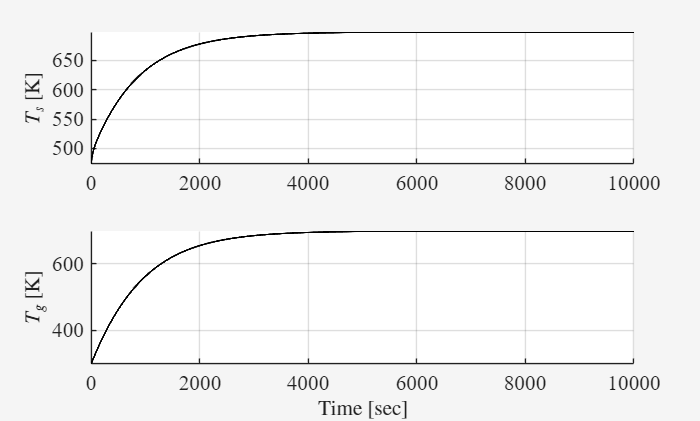

% Model paramters (RG)
% System parameters
kc = 0.8;      % convection constant of the oven [W/K]
kg = 1.5;      % convection constant of the product [W/K]
kr = 7.8e-10;  % radiation constant of the oven [W/K^4]
Cs = 85;      % heat capacity of the oven [J/K]
Cg = 700;      % heat capacity of the product [J/K]
k  = 100;      % power constant [W/V]
C2K = 273.15;  % conversion from degree Celsius to Kelvin (e.g. 20 degree Celsius = 20 + C2K Kelvin)

% Initial conditions for testing the Simulink model (RG)
Ta0 = 25; % ambient temperature [degree Celsius]
Ta0K = Ta0 + C2K; % ambient temperature [K]
Ts0 = 200; % oven surface temperature [degree Celsius]
Ts0K = Ts0 + C2K; % oven surface temperature [K]
Tg0 = 25; % product temperature [degree Celsius]
Tg0K = Tg0 + C2K; % product temperature [K]
u0 = 5; % voltage to power supply [V]
umin = 0; % minimum voltage [V]
umax = 10; % maximum voltage [V]

% Test the provided high temperature oven (RG)
SIM_TIME = 10000; % simulation time (can be changed as needed)
STEP_SIZE = 1; % integration step size of Simulink (can be changed as needed)
% Change with the name of the model you are using
SIMULINK_FILENAME = 'HighTemperatureOven_Simulink2019b';
time = (0:STEP_SIZE:SIM_TIME)';
u = u0*ones(length(time),1);
Ta = Ta0K*ones(length(time),1); 
sim(SIMULINK_FILENAME,SIM_TIME,[],[time u Ta])

% Plot the temporal behaviour of the oven and product temperatures (RG)
Ts = logsout.getElement('Ts').Values.Data;
Tg = logsout.getElement('Tg').Values.Data;

figure, h1 = subplot(2,1,1); set(h1,'FontName','times','FontSize',16)
hold on, grid on
plot(time,Ts,'k','LineWidth',1.5)
ylabel('$T_s$ [K]','FontName','times','FontSize',16,'Interpreter','latex')
h2 = subplot(2,1,2); set(h2,'FontName','times','FontSize',16)
hold on, grid on
plot(time,Tg,'k','LineWidth',1.5)
ylabel('$T_g$ [K]','FontName','times','FontSize',16,'Interpreter','latex')
xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex')
theme("light")

### Open-loop system analysis

**Problem 1 [2 points]** Based on the system dynamics described in Eq. (1), determine the system state vector, input, disturbance and output. Exploiting the Simulink model HighTemperatureOven_SimulinkYYYYC compute the stationary state associated to the following initial conditions: $T_{a,0} = 21^\circ C, \; T_{g,0} = 10^\circ C, \; T_{s,0} = 220^\circ C, \; u_0 = 5V$.

% Your solution goes here
c2k = @(C) C + 273.15; % Quick function to convert from C to K
Ta0 = c2k(21); Tg0 = c2k(10);
Ts0 = c2k(220); u0 = 5;

x0 = [Ts0; Tg0];
U = [u0; Ta0];
y0 = Tg0;
[xss,uss,yss,dx] = trim('HighTemperatureOven_Simulink2019b',x0,U,y0,[],[1 2],[])

xss =   696.7151
  696.7151


uss =     5.0000
  294.1500


yss = 696.7151

dx = 1.0e-12 *

   -0.2321
         0


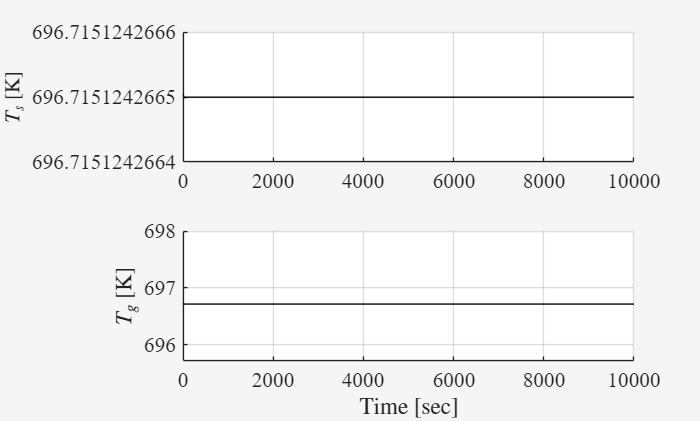

% Why is this necessary?
% Test to verify stationarity of the high temperature oven
SIM_TIME = 10000; % simulation time (can be changed as needed)
STEP_SIZE = 1; % integration step size of Simulink (can be changed as needed)
% Change with the name of the model you are using
SIMULINK_FILENAME = 'HighTemperatureOven_Simulink2019b';
time = (0:STEP_SIZE:SIM_TIME)';
u = u0*ones(length(time),1);
Ta = Ta0*ones(length(time),1); 
% Change the initial conditions of the integrators
Ts0K = xss(1);
Tg0K = xss(2);
% ------------
sim(SIMULINK_FILENAME,SIM_TIME,[],[time u Ta])

% Plot the temporal behaviour of the oven and product temperatures (RG)
Ts = logsout.getElement('Ts').Values.Data;
Tg = logsout.getElement('Tg').Values.Data;

figure, h1 = subplot(2,1,1); set(h1,'FontName','times','FontSize',16)
hold on, grid on
plot(time,Ts,'k')
ylabel('$T_s$ [K]','FontName','times','FontSize',16,'Interpreter','latex')
h2 = subplot(2,1,2); set(h2,'FontName','times','FontSize',16)
hold on, grid on
plot(time,Tg,'k')
ylabel('$T_g$ [K]','Interpreter','latex')
xlabel('Time [sec]','Interpreter','latex')
theme("light")

Then, numerically linearize the nonlinear model around the computed stationary state.

% Your solution goes here
[A,B,C,D] = linmod(SIMULINK_FILENAME,xss,uss)

A =    -0.0395    0.0176
    0.0021   -0.0021


B =     1.1765    0.0103
         0         0


C =      0     1


D =      0     0


Bv = B(:, 2);
B = B(:, 1);
D = D(:, 1);

**Problem 2 [2 points]** Evaluate the internal and the external stability of system.

% Your solution goes here
lambda_ol = eig(A)

lambda_ol =    -0.0405
   -0.0012


[num, den] = ss2tf(A, B, C, D);
G = minreal(tf(num, den));
eigenvalues = pole(G)

eigenvalues =    -0.0405
   -0.0012


System is internally asymptotic stable, so the system is also externally (BIBO) stable.

**Problem 3 [2 points]** Compute the system time constants, and determine the eigenmodes associated with the state response.

The system has real poles, so the time constants will be $\tau_i -\frac{1}{p_i }$

% Your solution goes here
% Time constants
tau_ol = -1./lambda_ol

tau_ol =    24.7161
  865.0935


### Control system design for temperature control

The main control objective is to regulate the temperature of the product at the desired reference temperature despite fluctuations in the environment temperature. 

Closed-loop system requirements

Let $T_{g,ref}(t)$ be the desired reference for the temperature of the product. Then the following closed-loop requirements should be fulfilled

- The product temperature $T_g$ is regulated to its desired reference value $T_{g,ref}(t)$ with zero steady state error for step changes in the reference value as well as in the ambient temperature $T_a$;

- For a step change of 25 degrees Celsius in $T_{g,ref}(t)$, the product temperature is regulated to the new reference value with a maximum overshoot of 2% and a settling time between 180 and 300 seconds;

- The control effor $u$ is kept in the range $[0,10]\, V$avoiding saturation as much as possible

**Problem 4 [6 points]** Under the assumption that the state is fully accessible design a discrete time controller that meets the aforementioned specifications.

% Your solution goes here
% Controllability test
Mc = ctrb(A,B);

if rank(Mc) == size(A,1)
    disp('Open loop linear system is controllable')
else
    disp('Open loop linear system is not controllable')
end

Open loop linear system is controllable


T_sett = 180; % selected settling time [s]
tau_sett = T_sett/5; % slowest time constant of closed loop system [s]
tau_ol = 1./abs(lambda_ol(abs(lambda_ol)>0));
Ts_max = min([tau_sett min(tau_ol)]./10) % maximum sampling time [s]

Ts_max = 2.4716

Ts = 2; % 1000 times smaller than desired settling time
[F,G] = c2d(A, B, Ts);
[~, Gv] = c2d(A, Bv, Ts);
Q = diag([0.00001 1/(0.02)^2]);
R = 10;

% Integral action
% F_aug = [F zeros(2, 1); -Ts*C 1];
% G_aug = [G; 0];
% C_aug = [C 0];

%[K_opt,S,lambda_cl_dt] = dlqr(F_aug, G_aug, Q*Ts, R*Ts)
% sys_cl_dt = ss(F_aug - G_aug*K_opt, G_aug, C_aug, D, Ts);
[K_opt,S,lambda_cl_dt] = dlqr(F, G, Q*Ts, R*Ts)

K_opt =     0.1829   12.2026


S = 1.0e+04 *

    0.0002    0.0132
    0.0132    2.0265


lambda_cl_dt =    0.7231 + 0.2082i
   0.7231 - 0.2082i


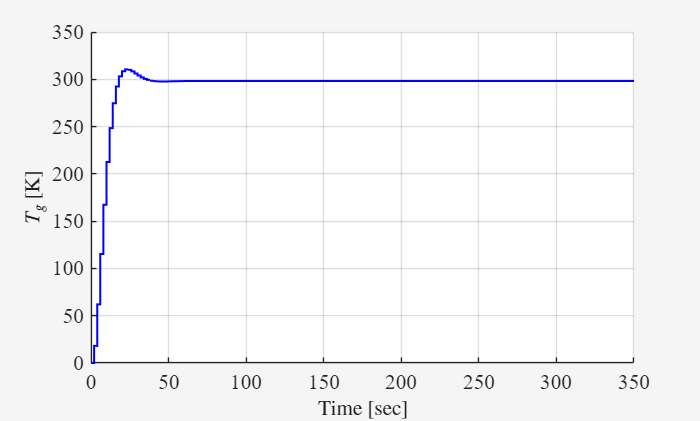

N = inv(C*inv(eye(2)-(F-G*K_opt))*G);
sys_cl_dt = ss(F - G*K_opt, G*N, C, D, Ts);


% Simulate closed-loop step response
t_STEP = 10; % 10 seconds into the simulation
x_ref0 = c2k(25);
x_ref = x_ref0*(ones(length(time(1:Ts/STEP_SIZE:end)),1));
ref = x_ref;
[y,t,x_lin] = lsim(sys_cl_dt, ref, time(1:Ts/STEP_SIZE:end));
u_ctrl_lin = -K_opt*x_lin' + N*x_ref';

figure, h6 = axes; set(h6,'FontName','times','FontSize',16)
hold on
stairs(t,y,'b','LineWidth',1.5)
ylabel('$T_g$ [K]','FontName','times','FontSize',16,'Interpreter','latex')
xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex')
xlim([0,350])
theme("light")
grid on

overshoot_lin = 100*(x_ref0 - max(y)) / x_ref0;
disp(['The overshoot of the linear response is ', num2str(overshoot_lin), '%'])

The overshoot of the linear response is -4.1149%


Too big overshoot. Trying with pole placement.

lambda_des_ct = [lambda_ol(1) -1/tau_des -0.03]

lambda_des_ct =    -0.0405   -0.0278   -0.0300


lambda_des_dt = exp(lambda_des_ct*Tsampl)

lambda_des_dt =     0.9223    0.9460    0.9418


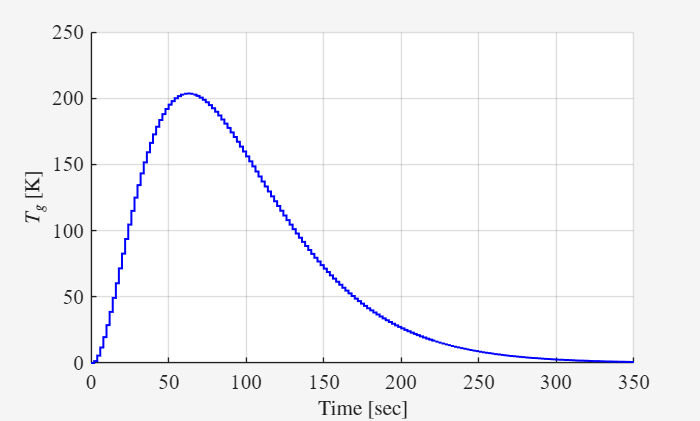


% Add integral action to ensure perfect reference tracking and disturbance
% rejection
Fi = [F zeros(2,1);
     -Tsampl*C 1];
Gi = [G; 0];
Gr = [zeros(2,1);
      Tsampl];

Kpp = place(Fi, Gi, lambda_des_dt);
Kfs = K(1:2);
Ki = -K(3);
xi0 = 0;

sys_cl_dt = ss(Fi - Gi*Kpp, Gi, [C 0], D, Ts);

% Simulate closed-loop step response
t_STEP = 10; % 10 seconds into the simulation
x_ref0 = c2k(25);
x_ref = x_ref0*(ones(length(time(1:Ts/STEP_SIZE:end)),1));
ref = x_ref;
[y,t,x_lin] = lsim(sys_cl_dt, ref, time(1:Ts/STEP_SIZE:end));

figure, h6 = axes; set(h6,'FontName','times','FontSize',16)
hold on
stairs(t,y,'b','LineWidth',1.5)
ylabel('$T_g$ [K]','FontName','times','FontSize',16,'Interpreter','latex')
xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex')
xlim([0,350])
theme("light")
grid on

Solution manual not tracking temp?

**Problem 5 [2 points]** Implement the discrete time controller in the Simulink model of the nonlinear system, and evalute the closed-loop system performance against the given requirements, when the sytem is subject to first a step change in reference temperature ($T_{g,ref}$ changes from $T_{g,ss}$ to $T_{g,ss} + 25^\circ C$, where $T_{g,ss}$ is the steady state product temperature computed in Problem 1) and then to a step change in ambient temperature ($T_a$ changes from $T_{a,0}$ to $T_{a,0} + 10^\circ C$).

% Your solution goes here



### State estimation for output feedback control

In order to implement an output feedback controller for the temperature control, the state vector must be estimated based on the available measurement of product temperature $T_g$. In the last part of the exercise, we assume the following measurement model

$y_1 = T_g + v_1$                            (2)

where $v_1$ is zero mean white noise. The noise amplitude is $\pm1.5^\circ C$. 

Further, we assume that the ambient temperature $T_a$ is given by the sum of two components


$$T_a = \bar{T_{a}} + T_{a,f}$$


where $\bar{T_a}$ is the mean ambient temperature and $T_{a,f}$ is the ambient temperature fluctuation, which is modeled as band-limited noise characterized by the following autocorrelation function


$$R_{T_a}(\tau)= \sigma_{a}^2 \; e^{-\beta_a|\tau|} $$


with $\sigma_a = 0.5^\circ C$ and $\beta_a = 0.008$.

**Problem 6 [6 points]** Under the assumption that the mean ambient temperature $\bar{T_a}$ is unknown, design a discrete time Kalman filter able to estimate the oven surface temperature $T_s$, the product temperature $T_g$, and the mean ambient temperature $\bar{T_a}$.

% Your solution goes here





**Problem 7 [4 points]** Implement the discrete time Kalman filter in the Simulink diagram of the open-loop system and assess its estimation performance when the open-loop system is subject to a step change in mean ambient temperature ($\bar{T_a}$ changes from $\bar{T_a} = T_{a,0}$ to $\bar{T_a} = T_{a,0} + 10^\circ C$)

% Your solution goes here



